clear all
syms x(t) y(t) theta(t) Ff(t) N(t)

m = 1;      % kg
r = 0.1;    % m
g = 9.81;     % m/s^2
Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

rG=[x(t);y(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(rG,t,t)==F-m*g*[0;1]

$$eq1 = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\mathrm{Ff}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=N\left(t\right)-\frac{981}{100} \end{array}\right)$$


% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3)

$$eq2 = \frac{921972451898689\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{288230376151711744}=-\mathrm{Ff}\left(t\right)\,\left(\frac{6116438548504169\,\cos\left(\theta \left(t\right)\right)}{144115188075855872}-\frac{1}{10}\right)-\frac{6116438548504169\,\sin\left(\theta \left(t\right)\right)\,N\left(t\right)}{144115188075855872}$$


% roll without slip
vG = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = diff(rG,t) == vG(1:2);



Initial Conditions:
Y0/YP0:
x: -0.031139 xt:0.000000
y: 0.063245 yt:0.000000
Ff: 1.721276 Fft:0.000000
N: 9.232456 Nt:0.000000
theta: 0.523599 thetat:0.000000
Dxt: 0.000000 Dxtt:1.721276
Dyt: 0.000000 Dytt:-0.577544
Dthetat: 0.000000 Dthetatt:-27.216117


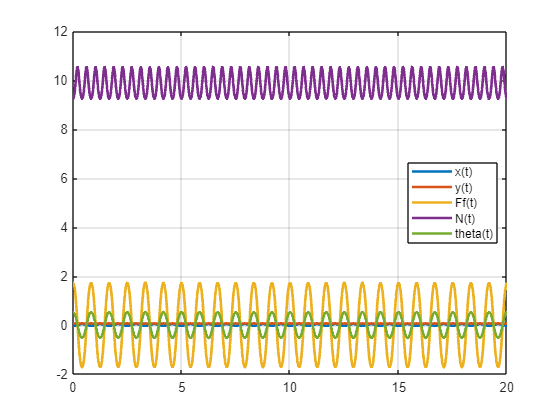



theta0 = pi/6;
omega0 = 0;
R_b_I = [cos(theta0) -sin(theta0) 0;sin(theta0) cos(theta0) 0;0 0 1];
temp = [-r*theta0;0;0] + [0;r;0] + R_b_I*[0;-4*r/(3*pi);0];
rGx0 = temp(1);
rGy0 = temp(2);


DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];
soln=mechanicsAsDAE(DES,disp_const,vel_const,[rG;F;theta],...
    0,20,{x==rGx0,y==rGy0,theta==theta0,diff(theta)==omega0});

[pureODEs,PPs]=analyzeSystem(DES,[],vel_const,[diff(rG);F;theta],[theta,diff(theta)])

There are 7 equations, and 5 unknown time-varying functions.
The non-algebraic (force) functions are:
Ff(t)
N(t)

Adding in all constraints, and counting pure symbols (so that x, Dxt, Dxtt count as 3 symbols) I get:
equations: 7
symbols:9
free parameters: 2.

Expected number of state variables: 2



$$pureODEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{220367922943023303462492508782592\,\sin\left(\theta \left(t\right)\right)\,\left(10\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+981\right)}{4407358458860466069249850175651840\,\cos\left(\theta \left(t\right)\right)-7788445287802241602543245460631721}$$

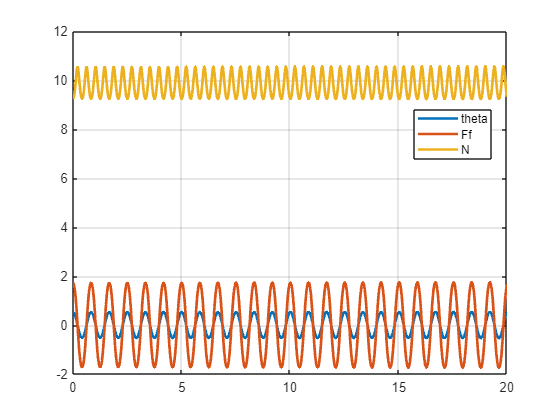

soln=timeStepODESystem(pureODEs,theta,[theta==theta0,diff(theta)==omega0],[0,20],PPs);
plot(soln.t,soln.theta,soln.t,soln.Ff,soln.t,soln.N,'LineWidth',2)
legend({"theta","Ff","N"},'Location','Best')
grid on